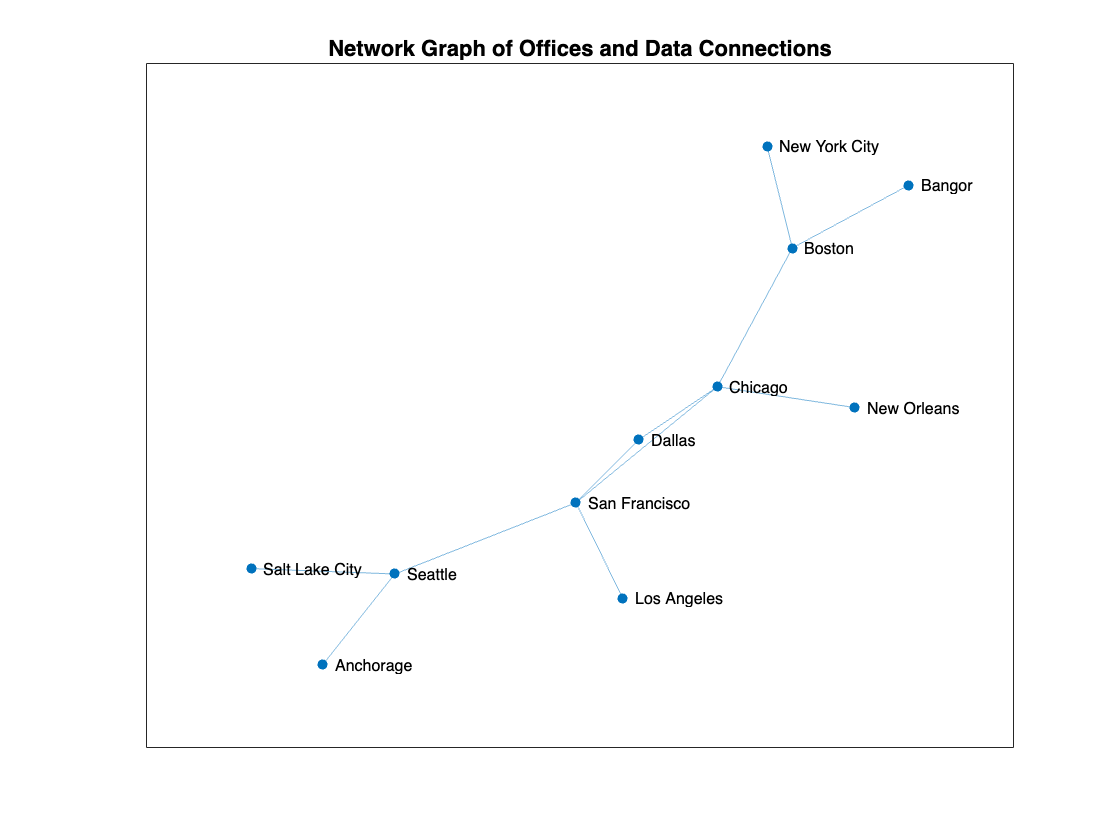

% Step 1: Define the adjacency matrix for the given network (symmetric version)
A = [0 1 0 0 0 0 0 0 0 0 0;
     1 0 1 1 0 0 0 0 0 0 0;
     0 1 0 0 0 0 0 0 0 0 0;
     0 1 0 0 1 1 1 0 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 1 0 0 1 1 0 1 0;
     0 0 0 1 0 1 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0;
     0 0 0 0 0 1 0 0 1 0 1;
     0 0 0 0 0 0 0 0 0 1 0];

% Ensure the matrix is symmetric (undirected graph)
A = A + A';

% Step 2: Create the graph
G = graph(A);

% Step 3: Define the node labels (city names)
nodeLabels = {'Anchorage', 'Seattle', 'Salt Lake City', 'San Francisco', ...
              'Los Angeles', 'Chicago', 'Dallas', 'New Orleans', ...
              'New York City', 'Boston', 'Bangor'};

% Step 4: Plot the graph
figure;
plot(G, 'NodeLabel', nodeLabels);
title('Network Graph of Offices and Data Connections');


% Steps 5-8: Existing code (articulation points, bridges, betweenness centrality, max flow)
% [Existing code remains unchanged]

% New Step: Calculate the number of hops between each pair of cities
numNodes = numnodes(G);
numHops = zeros(numNodes, numNodes); % Initialize matrix to store number of hops

for i = 1:numNodes
    for j = 1:numNodes
        if i ~= j
            [P, ~] = shortestpath(G, i, j); % Find shortest path between nodes i and j
            numHops(i, j) = length(P) - 2;  % Number of hops is the number of intermediate nodes
        else
            numHops(i, j) = 0; % No hops needed if origin and destination are the same
        end
    end
end

% Display the number of hops in a table format
cityPairs = {};
hopsList = [];
for i = 1:numNodes
    for j = 1:numNodes
        if i ~= j
            cityPairs = [cityPairs; [nodeLabels{i}, ' to ', nodeLabels{j}]];
            hopsList = [hopsList; numHops(i, j)];
        end
    end
end

T = table(cityPairs, hopsList, 'VariableNames', {'Route', 'NumberOfHops'});
disp('Number of Hops Between Each Pair of Cities:');

Number of Hops Between Each Pair of Cities:


disp(T);

                   Route                   NumberOfHops
    ___________________________________    ____________

    {'Anchorage to Seattle'           }         0      
    {'Anchorage to Salt Lake City'    }         1      
    {'Anchorage to San Francisco'     }         1      
    {'Anchorage to Los Angeles'       }         2      
    {'Anchorage to Chicago'           }         2      
    {'Anchorage to Dallas'            }         2      
    {'Anchorage to New Orleans'       }         3      
    {'Anchorage to New York City'     }         4      
    {'Anchorage to Boston'            }         3      
    {'Anchorage to Bangor'            }         4      
    {'Seattle to Anchorage'           }         0      
    {'Seattle to Salt Lake City'      }         0      
    {'Seattle to San Francisco'       }         0      
    {'Seattle to Los Angeles'         }         1      
    {'Seattle to Chicago'          